# ΨΗΦΙΑΚΕΣ ΤΗΛΕΠΙΚΟΙΝΩΝΙΕΣ

## 1ο σετ Εργαστηριακών Ασκήσεων 

Λουδάρος Ιωάννης - ΑΜ 1067400

% Μεταφορά του Current Folder στον κατάλογο του αρχείου ώστε να υπάρχει
% πρόσβαση στις απαιτούμενες συναρτήσεις.

cd(fileparts(matlab.desktop.editor.getActiveFilename))

### Μέρος 1

#### LloydMax 

[Άνοιγμα Ορισμού](matlab:open('./LloydMax.m'))

Κατασκευάστηκε η παρακάτω συνάρτηση 

Είσοδοι:

- $x$ : Το σήμα εισόδου υπό την μορφή διανύσματος

- $N
$: Ο αριθμός των bits/sample που θα χρησιμοποιηθούν

- $max_{value$ : Η μέγιστη αποδεκτή τιμή του σήματος εισόδου

- $min_{value}$ : Η ελάχιστη αποδεκτή τιμή του σήματος εισόδου

Έξοδοι:

- $x_q$ : Το κωδικοποιημένο διάνυσμα εξόδου μετά από $K_{max}$ επαναλήψεις του αλγορίθμου

- $\text{centers}$ : Τα κέντρα των περιοχών κβάντισης μετά από $K_{max}$ επαναλήψεις του αλγορίθμου.

- $D$ : Διάνυσμα που περιέχει τις τιμές [$D_1 : D_{K_{max}}$], όπου το $D_i$ αντιστοιχεί στη μέση παραμόρφωση την i-οστή επανάληψη του αλγορίθμου

Η συνάρτηση ορίζεται στο αρχείο LloydMax.m που βρίσκεται στον ίδιο κατάλογο με το παρόν αρχείο.

**Παράδειγμα χρήσης:**

min_value = 1;
max_value = 100;
N = 4;
qlevels = linspace(min_value, max_value, 2^N+2);
qlevels = qlevels(2:end-1);
x = 120*rand(1, 100)-10

x =    40.6564   85.6766  107.3664   -3.5113   81.3561   74.3750   -3.0502    6.6788   91.4332   99.1308   72.1766   19.3175   72.0187   52.2696   97.9278   17.5092   38.1344   73.6407   16.7981   25.7099   14.1371   58.3750  102.2024   98.4436   -9.4898   88.5471  104.7601   36.1930   55.7501   36.6232   87.1775   98.0483   69.9283   10.4235   33.5166   45.8547   10.4942   98.9455  103.4558   20.0302   90.5909   32.9157   41.9275   28.8340   86.5511   94.2962   91.0890   44.0058   21.5311   94.8545






[xq, centers, D] = LloydMax(x, N, min_value, max_value)

xq = 100×4 char array
    '0110'
    '1101'
    '1111'
    '0000'
    '1101'
    '1100'
    '0000'
    '0000'
    '1110'
    '1111'
    '1011'
    '0010'
    '1011'
    '1000'
    '1111'
    '0010'
    '0101'
    '1011'
    '0010'
    '0011'
    '0001'
    '1001'
    '1111'
    '1111'
    '0000'
    '1110'
    '1111'
    '0101'
    '1000'
    '0101'
    '1110'
    '1111'
    '1011'
    '0001'
    '0101'
    '0111'
    '0001'
    '1111'
    '1111'
    '0010'
    '1110'
    '0100'
    '0110'
    '0100'
    '1101'
    '1111'
    '1110'
    '0110'
    '0011'
    '1111'
    '0000'
    '1101'
    '0101'
    '1101'
    '1011'
    '1101'
    '1000'
    '1010'
    '1000'
    '0111'
    '1100'
    '0101'
    '1101'
    '0001'
    '0001'
    '0000'
    '1101'
    '1111'
    '1000'
    '1011'
    '1101'
    '0001'
    '1110'
    '0100'
    '1101'
    '1101'
    '0000'
    '0000'
    '0110'
    '0010'
    '0100'
    '1111'
    '0101'
    '1101'
    '1111'
    '1010'
    '1101'
    '1100'
    '0010'

centers =     2.5664   11.6330   17.9616   23.6205   30.6073   35.9615   41.8071   46.2302   53.5087   58.3750   64.1427   71.5445   75.7869   84.0098   90.1753   98.2951


D =     7.9823    3.8172    3.7187    3.7006    3.5775    3.5317    3.5134    3.5134


#### Delta Modulation

[Άνοιγμα Ορισμού](matlab:open('./adm.m'))

![...]

#### Πηγές που θα χρησιμοποιηθούν

**Α. AR(1) διαδικασία**

L=10000;
x=randn(L,1);
a1=0.9;
a2=0.01;

ar1 = filter(1,[1; -a1], x);
ar2 = filter(1,[1; -a2], x);


**Β. Εικόνα**

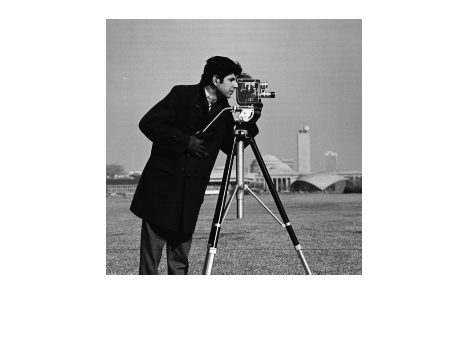

load cameraman.mat
imshow(uint8(i));

x=i(:);
x=((x-128)/128);


#### Ζητούμενο 1

![...]

#### Ζητούμενο 2

binary_seq =      0
     0
     0
     1
     1
     1
     0
     1
     0
     0


![...]

### Μέρος 2

Για το δεύτερο μέρος κατασκευάστηκαν πολλαπλές συναρτήσεις που βρίσκονται στον ίδιο κατάλογο με το παρόν αρχείο.

#### Ο Mapper

[Άνοιγμα Ορισμού](matlab:open('./mapper.m'))

**Είσοδοι**

- bin_seq : Δυαδική ακολουθία προς μετατροπή σε σύμβολα.

- Μ : Το πλήθος των συμβόλων.

- gray : Επιλογή για το αν η ακολουθία συμβόλων θα είναι κωδικοποιημένη κατά gray (1) ή όχι (0).

**Έξοδοι**

- symbol_seq : Η ακολουθία συμβόλων που προκύπτει.

- chopped : bits της άρχικης ακολουθίας που αποκόπηκαν γιατί δεν μπορούσαν να γίνουν map.

#### Ο Demapper

[Άνοιγμα Ορισμού](matlab:open('./demapper.m'))

**Είσοδοι**

- symbol_seq : Η ακολουθία συμβόλων που παραλαμβάνεται.

- Μ : Το πλήθος των συμβόλων.

- gray : Επιλογή για το αν η ακολουθία συμβόλων είναι κωδικοποιημένη κατά gray (1) ή όχι (0).

- chopped : bits της άρχικης ακολουθίας που αποκόπηκαν γιατί δεν μπορούσαν να γίνουν map. Θα προστεθούν απλά στο τέλος, αν δοθούν.

**Έξοδοι**

- bin_seq : Δυαδική ακολουθία που προκύπτει από τα σύμβολα.

**Παράδειγμα χρήσης**

binary_seq = randsrc(100,1,[0, 1])
M=8;
gray=0;


chopped = 1

symbol_seq =      0     7     2     3     3     2     0     7     0     1     0     3     2     1     3     6     4     5     7     2     0     4     1     1     6     3     5     0     4     7     6     7     7


[chopped, symbol_seq] = mapper (binary_seq, 8, 0)

binary_seq = "0001110100110110100001110000010000110100010111101001011110100001000010011100111010001001111101111111"

binary_seq = demapper(symbol_seq, M, gray, chopped)

#### Ο Modulator

[Άνοιγμα Ορισμού](matlab:open('./modulator.m'))

**Είσοδοι**

- symbol_seq : Τα προς μετάδοση σύμβολα.

- Μ : Το πλήθος των συμβόλων.

**Έξοδοι**

- modulated : Ο προς μετάδoση παλμός.

#### Ο Demodulator

[Άνοιγμα Ορισμού](matlab:open('./demodulator.m'))

**Είσοδοι**

- received_signal : Το σήμα που παραλάβαμε από το κανάλι.

**Έξοδοι**

- demodulated : Το demodulated σήμα.

**Παράδειγμα χρήσης**

zsh:1: no matches found: [...]


#### O Detector

[Άνοιγμα Ορισμού](matlab:open('./detector.m'))

**Είσοδοι**

- demodulated : Το αποδιαμορφωμένο σήμα από το κανάλι.

- Μ : Το πλήθος των συμβόλων.

**Έξοδοι**

- symbol_seq : Η ακολουθία συμβόλων που εξάγαμε.

#### Ζητούμενο 1

#### Ζητούμενο 2

#### Ζητούμενο 3

#### Ζητούμενο 4

#### Ζητούμενο 5